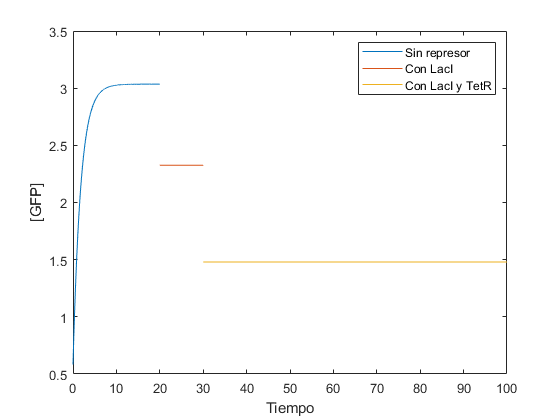

%Constantes%
ktr=rand;
kd=rand;
H1=rand;
H2=rand;
GFP0=rand;
t1=20;
t2=30;
LacI0=rand;
TetR0=rand;
T1=0:.01:t1;
T2=t1:.01:t2;
T3=t2:.01:100;
%Ecuaciones%
GFPmax1=ktr/kd*(1/(1+0/H1)+1/(1+0/H2));
GFP1=GFPmax1*(1-exp(-kd*T1))+GFP0*exp(-kd*T1);
GFPmax2=ktr/kd*(1/(1+LacI0/H1)+1/(1+0/H2));
GFP2=GFPmax2*(1-exp(-kd*T2))+GFP0*exp(-kd*T2);
GFPmax3=ktr/kd*(1/(1+LacI0/H1)+1/(1+TetR0/H2));
GFP3=GFPmax3*(1-exp(-kd*T3))+GFP0*exp(-kd*T3);
%Gráficas%
plot(T1,GFP1)
hold on
plot(T2,GFP2)

plot(T3,GFP3)